clc;
clear all;

## **Case Study: 6-bus system, 10-phase**

T=10;
N=6;

linedata=[1	2	0.0370 200
1       4       0.0160 200
2	3	0.1015 175
2	4	0.1170 175
3	6	0.0355 175
4	5	0.0370 200
5	6	0.1270 200];
M=size(linedata,1);
H= GSDF(linedata);
fmax=linedata(:,4);

bb= [0;0;0;50;0;0];

d_r=[0 50 50 150 0 75;0 60 90 180 0 70;0 30 90 190 0 72;0 50 40 150 0 77;
    0 69 105 160 0 79;0 24 57 170 0 34;0 56 76 129 0 40;0 60 90 172 0 60;
    0 50 100 176 0 65;0 30 108 134 0 80];  % concerned with T

p_raw=[1.2 0.8 0 0 1.4 1.4;2.8 1.8 0 0 2.4 2.4;4.4 2.8 0 0 2.4 2.4];
q=[0 0 0 0 0 0;-80 -50 0 0 -40 -40;-240 -150 0 0 -40 -40];

gmin=[50;50;0;0;30;25];
gmax=[250;200;0;0;80;100];

ramp_ratio=[0.3;0.15;0;0;0.2;0.1];
UR=gmax.*ramp_ratio;
DR=gmax.*ramp_ratio;

ramp_rate=0.5;
umin=-bb*ramp_rate;
umax=bb*ramp_rate;

***emission infomation***

carbon_tax=0.2;
emission_info=[2 1 0 0 0.5 0.5];
p=p_raw+emission_info*carbon_tax;

**Uncertain Part : At Bus 4 -- wind turbine**

w_loc=[4];
w_num=size(w_loc,1);
real_capacity_scale=20;
w_f= [0 0 0 30 0 0;0 0 0 10 0 0;0 0 0 15 0 0;0 0 0 20 0 0;
    0 0 0 32 0 0;0 0 0 20 0 0;0 0 0 16 0 0;0 0 0 30 0 0;
    0 0 0 10 0 0;0 0 0 20 0 0]; % concerned with T
d_f= d_r-w_f;
filename='.\data\WindGenTotalLoadYTD_2020.xls';
error_data= gen_wind_data(real_capacity_scale,filename);

virtual_bb=[bb bb bb];
real_bb=zeros(N,3);
epsilon=0.1;
gamma=0.4;
if sum(bb)~=0
    for flag=1:3
        for k=1:w_num
            i=w_loc(k);
            virtual_bb(i,flag)= gen_virtual_storage_capacity(bb(i),epsilon,T,gamma,error_data,flag);
        end
        [standard_delta,real_bb(:,flag)]= gen_standard_delta(bb,virtual_bb(:,flag),w_loc);
    end
end

x=zeros(T*N*4,3);
fval=zeros(1,3);
for flag=1:3
    [x(:,flag),fval(:,flag)]=MinC(T,N,M,real_bb(:,flag),d_f,p,q,H,fmax,gmin,gmax,umin,umax,DR,UR);
end

**A Clairvoyant Circumstance**

[x_ori,fval_ori]=MinC(T,N,M,bb,d_f,p,q,H,fmax,gmin,gmax,umin,umax,DR,UR);
error_q=0.01;
exam_MinC(T,N,M,bb,d_f,p,q,H,fmax,gmin,gmax,umin,umax,x_ori,fval_ori,error_q);

charging decision:
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
   25.0000  -25.0000  -25.0000   25.0000  -25.0000   25.0000   25.0000  -11.8833  -21.4916    8.3749
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0

line flow:
  -16.9483  -16.0111  -23.2913  -20.7175    5.0749  -35.3261  -12.8883   -7.7333  -20.0344  -12.2947
   66.9483   71.0111   73.2913   70.7175   54.9251   85.3261   62.8883   57.7333   70.0344   62.2947
   18.5366   39.2146   41.3204   13.0601   52.8521   10.5174   18.4358   32.0427   43.5609   55.6732
   14.5150   14.7743   17.3883   16.2224    5.9062   22.8400

**Storage operation**

s_loc=w_loc(1);
U_temp=reshape(x_ori(T*N+1:2*T*N),N,T);
U_ori=U_temp(s_loc,:);
U_temp=reshape(x(T*N+1:2*T*N,1),N,T);
U_CC=U_temp(s_loc,:);
U_temp=reshape(x(T*N+1:2*T*N,3),N,T);
U_DRO=U_temp(s_loc,:);

**plot**

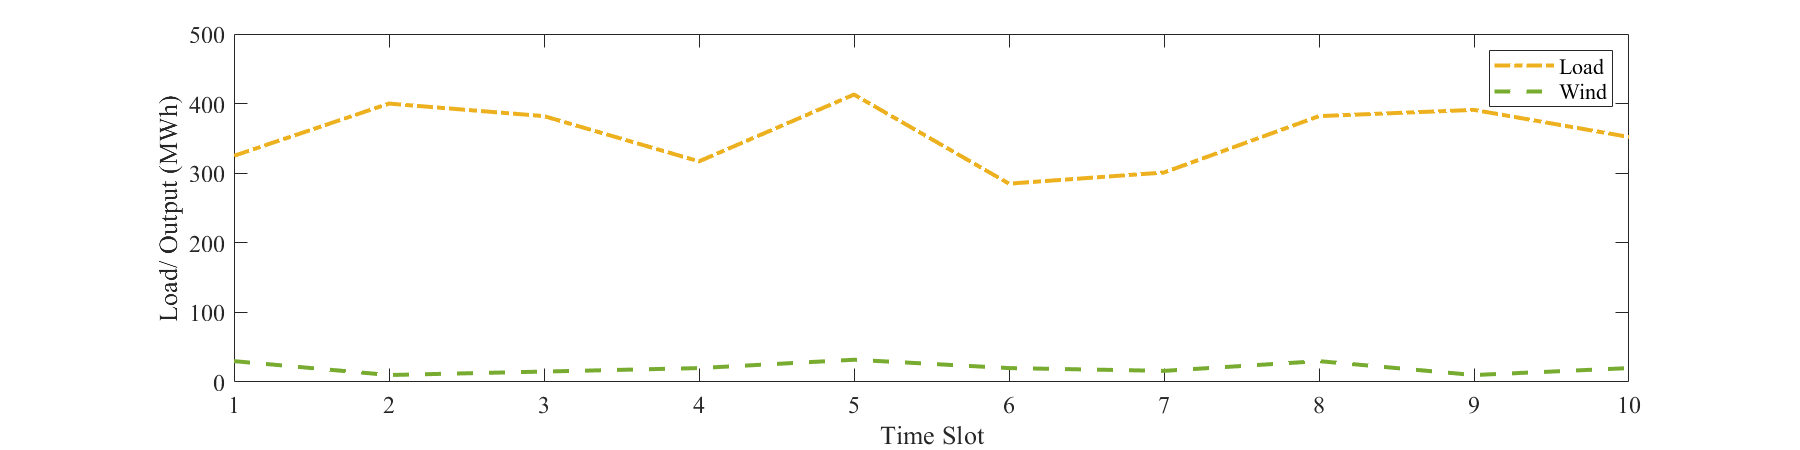

figure
xx=1:T;
dr_all=sum(d_r,2);
wf_all=sum(w_f,2);
plot(xx,dr_all,'-.','color',[0.9290 0.6940 0.1250],'lineWidth',2);
hold on
plot(xx,wf_all,'--','color',[0.4660 0.6740 0.1880],'lineWidth',2);
legend('Load','Wind')
ylabel('Load/ Output (MWh)' ,'FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
xlabel('Time Slot','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
set(gcf,'Position',[100 100 1200 300]);
set(gca,'FontSize',12,'FontName','Times New Roman')

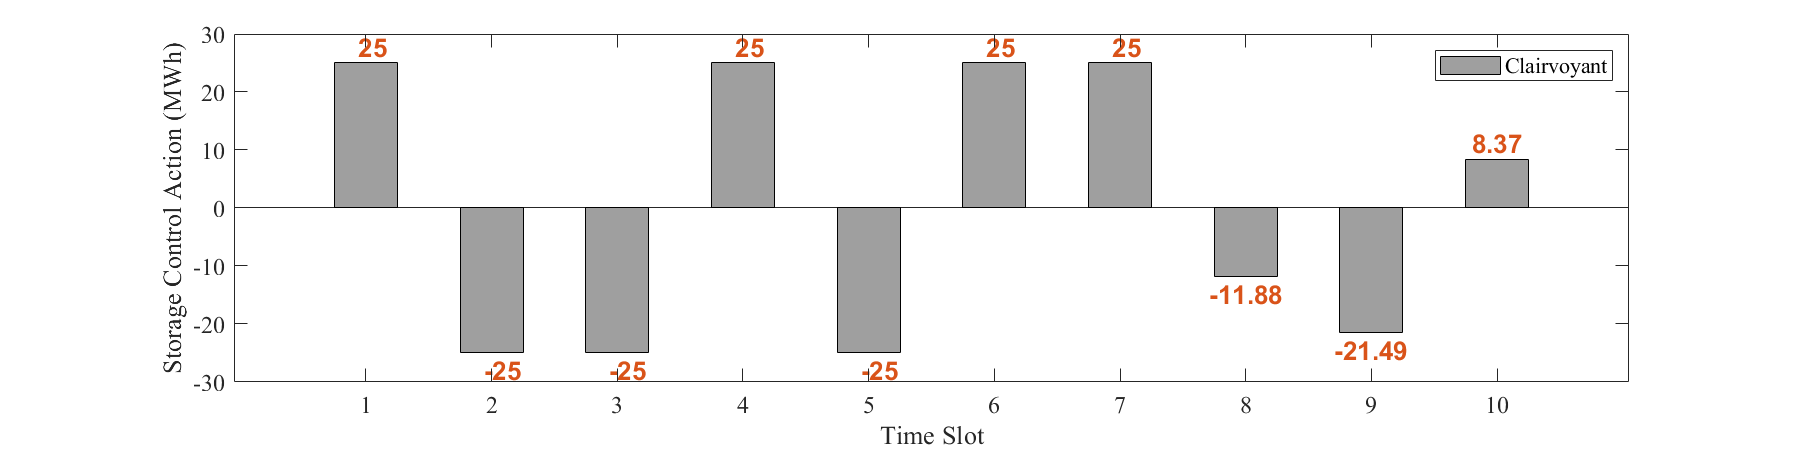

figure
b=bar(xx,U_ori,0.5);
b.FaceColor=[0.25, 0.25, 0.25];
b.FaceAlpha=.5;

Y_temp=U_ori(U_ori>0);
Y_loc=find(U_ori>0);
Y=roundn(Y_temp,-2);
text(Y_loc,Y,num2str(Y'),'vert','bottom','horiz','center','FontSize',13,'Color',[0.8500, 0.3250, 0.0980],'FontWeight','Bold'); 

Y_temp=U_ori(U_ori<0);
Y_loc=find(U_ori<0);
Y=roundn(Y_temp,-2);
text(Y_loc,Y,num2str(Y'),'vert','top','horiz','center','FontSize',13,'Color',[0.8500, 0.3250, 0.0980],'FontWeight','Bold'); 


ylabel('Storage Control Action (MWh)' ,'FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
xlabel('Time Slot','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
set(gcf,'Position',[100 100 1200 300]);
set(gca,'FontSize',12,'FontName','Times New Roman')
legend('Clairvoyant')

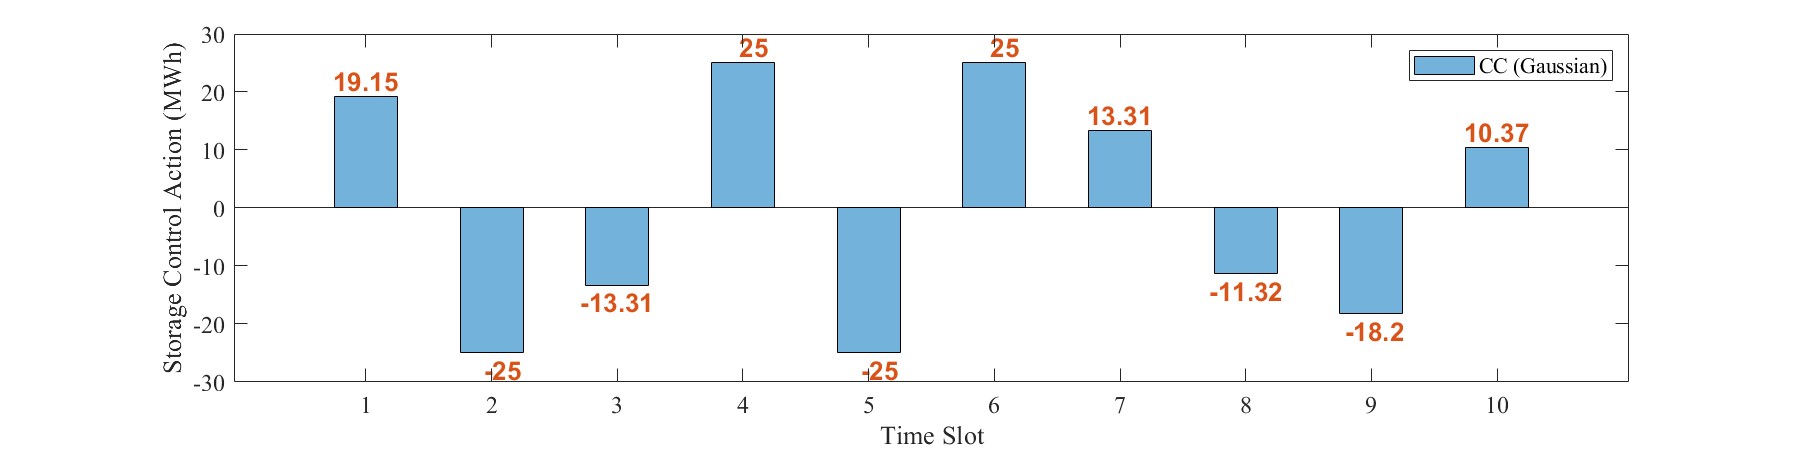

figure
b=bar(xx,U_CC,0.5);

Y_temp=U_CC(U_CC>0);
Y_loc=find(U_CC>0);
Y=roundn(Y_temp,-2);
text(Y_loc,Y,num2str(Y'),'vert','bottom','horiz','center','FontSize',13,'Color',[0.8500, 0.3250, 0.0980],'FontWeight','Bold'); 

Y_temp=U_CC(U_CC<0);
Y_loc=find(U_CC<0);
Y=roundn(Y_temp,-2);
text(Y_loc,Y,num2str(Y'),'vert','top','horiz','center','FontSize',13,'Color',[0.8500, 0.3250, 0.0980],'FontWeight','Bold'); 

b.FaceColor=[0, 0.4470, 0.7410];
b.FaceAlpha=.55;
ylabel('Storage Control Action (MWh)' ,'FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
xlabel('Time Slot','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
set(gcf,'Position',[100 100 1200 300]);
set(gca,'FontSize',12,'FontName','Times New Roman')
legend('CC (Gaussian)')

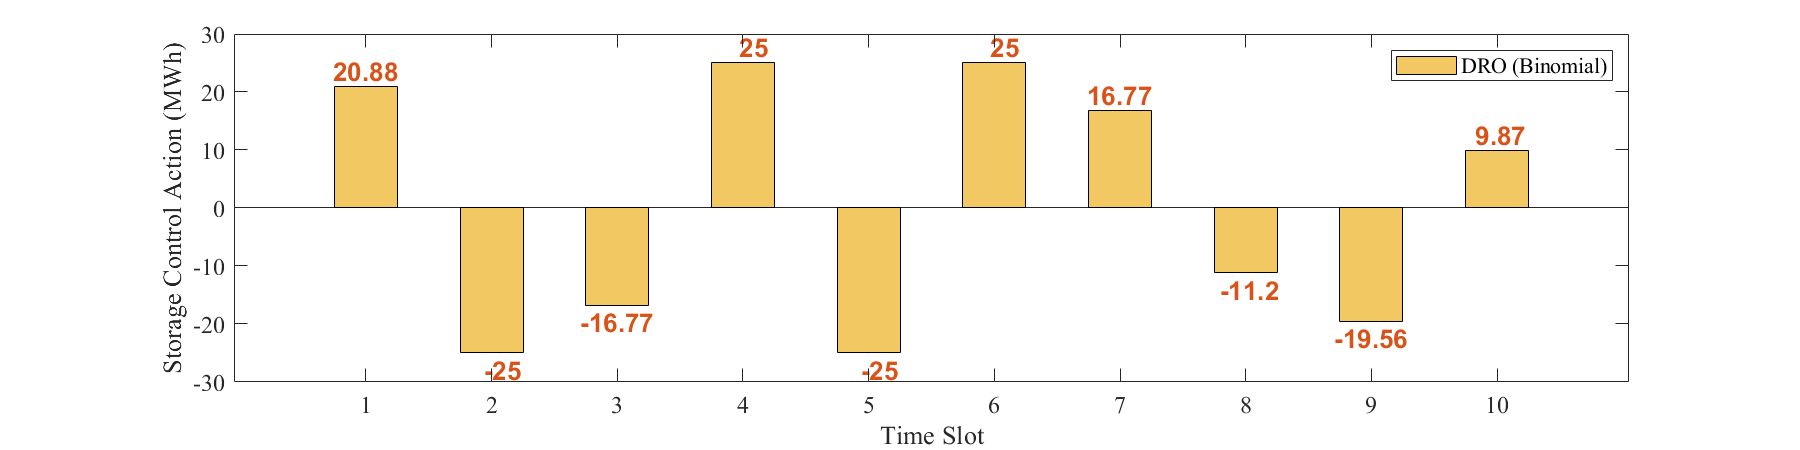

figure
b=bar(xx,U_DRO,0.5);

Y_temp=U_DRO(U_DRO>0);
Y_loc=find(U_DRO>0);
Y=roundn(Y_temp,-2);
text(Y_loc,Y,num2str(Y'),'vert','bottom','horiz','center','FontSize',13,'Color',[0.8500, 0.3250, 0.0980],'FontWeight','Bold'); 

Y_temp=U_DRO(U_DRO<0);
Y_loc=find(U_DRO<0);
Y=roundn(Y_temp,-2);
text(Y_loc,Y,num2str(Y'),'vert','top','horiz','center','FontSize',13,'Color',[0.8500, 0.3250, 0.0980],'FontWeight','Bold'); 


b.FaceColor=[0.9290 0.6940 0.1250];
b.FaceAlpha=.7;
ylabel('Storage Control Action (MWh)' ,'FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
xlabel('Time Slot','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
set(gcf,'Position',[100 100 1200 300]);
set(gca,'FontSize',12,'FontName','Times New Roman')
legend('DRO (Binomial)')

**Generator Operation**

% s_loc=w_loc(1);
G_ori=reshape(x_ori(1:T*N),N,T);
G_CC=reshape(x(1:T*N,1),N,T);
G_DRO=reshape(x(1:T*N,3),N,T);
Gramp_ori=zeros(N,T-1);
Gramp_CC=zeros(N,T-1);
Gramp_DRO=zeros(N,T-1);
for t=1:(T-1)
    Gramp_ori(:,t)=G_ori(:,t+1)-G_ori(:,t);
    Gramp_CC(:,t)=G_CC(:,t+1)-G_CC(:,t);   
    Gramp_DRO(:,t)=G_DRO(:,t+1)-G_DRO(:,t);
end

Gramp_ori

Gramp_ori =     5.0000   -5.0000   -0.0000   10.0000  -10.0000    0.0000    0.0000   -0.0000    0.0000
   30.0000  -18.0000  -12.0000   22.6835  -30.0000    7.3165   10.1167   19.3916  -19.1334
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
    5.3050   -0.0000   -4.1491    0.8253  -16.0000    6.9150   12.4088    0.0000    0.0000
    4.6950   -0.0000   -3.8509    0.4912  -10.0000    5.7684    7.5912   -0.0000    0.0000


Gramp_CC

Gramp_CC =     5.0000   -5.0000   -0.0000   10.0000  -10.0000    0.0000    0.0000   -0.0000    0.0000
   30.0000   -6.3096  -23.6904   23.6158  -30.0000    4.6187   16.3686   18.1972  -20.4336
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
    9.3263   -0.0000   -4.1019    0.5376  -16.0000    1.7777   16.0000    1.7866    0.0000
    6.5189   -0.0000   -3.8981   -0.1534  -10.0000    1.9133   10.0000    2.1382    0.0000


Gramp_DRO

Gramp_DRO =     5.0000   -5.0000   -0.0000   10.0000  -10.0000    0.0000    0.0000    0.0000    0.0000
   30.0000   -9.7682  -20.2318   23.4429  -30.0000    5.6426   13.0351   19.3227  -19.5739
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
    8.0054   -0.0000   -4.1131    0.5917  -16.0000    2.7731   16.0000    0.7483    0.0000
    6.1105   -0.0000   -3.8869   -0.0345  -10.0000    3.3524   10.0000    0.5690    0.0000


DR

DR =     75
    30
     0
     0
    16
    10


fval_ori

fval_ori = 6.1840e+03

fval

fval = 	1.0e+03 *

    6.1956    6.2435    6.1913
